1. **Preparation and Preview of Source Data**

clear, close all,clc;

sEMG = load('SourceData.mat')

sEMG =       MoveOne: [6000x1 double]
      MoveTwo: [7000x1 double]
      RestOne: [5000x1 double]
    RestThree: [5000x1 double]
      RestTwo: [5000x1 double]


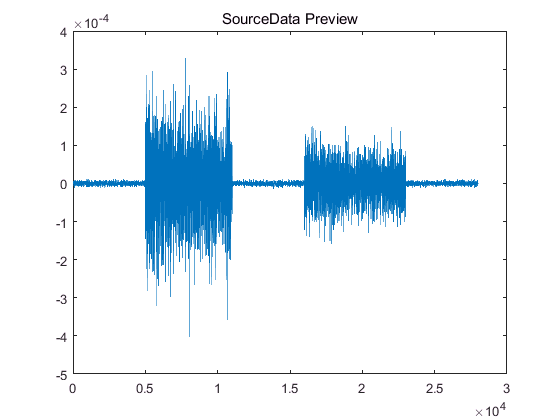

% Preparation
sEMG.AllData = [sEMG.RestOne; ...
                sEMG.MoveOne; ...
                sEMG.RestTwo; ...
                sEMG.MoveTwo; ...
                sEMG.RestThree];
            
sEMG.CellData = {sEMG.RestOne, ...
                 sEMG.MoveOne, ...
                 sEMG.RestTwo, ...
                 sEMG.MoveTwo, ...
                 sEMG.RestThree};
sEMG.StringTitle = {'RestOne', ...
                    'MoveOne', ...
                    'RestTwo', ...
                    'MoveTwo', ...
                    'RestThree'};
% preview
figure('Name', 'SourceData Preview');
plot(sEMG.AllData);
title('SourceData Preview');

**2. Time domain(be ignored in this discussion)**

**3. Frequency domain**

**    3.1 Fourier Transformation**

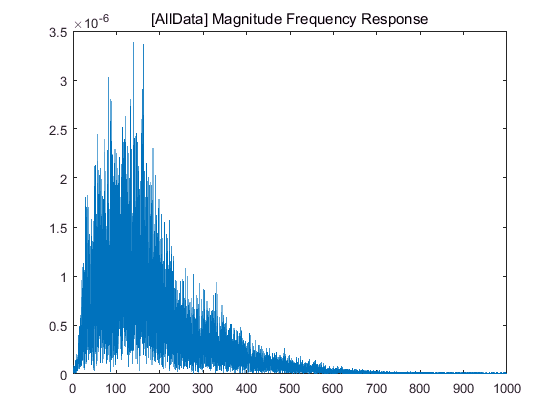

Fs = 2000; % Sampling Frequency 2K
[Magnitude, Phase, f] = FourierAnalysis(sEMG.AllData, Fs);

figure;
% subplot(2,1,1)
plot(f, Magnitude);
title('[AllData] Magnitude Frequency Response');


% subplot(2,1,2)
% plot(f, Phase);
% title('[AllData] Phase-Frequency Response');

**    Fourier Analysis of Five parts respectively.**

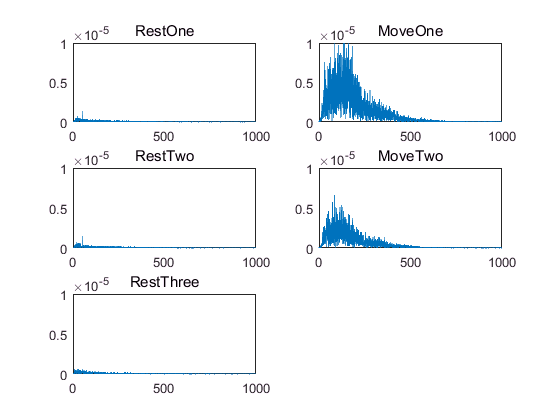

figure;
for p = 1:5
    ax = subplot(3,2,p);
    [M, P, f] = FourierAnalysis(sEMG.CellData{p}, Fs);
    plot(f, M);
    set(ax, 'YLim', [0,1*10^(-5)]);
    title(sEMG.StringTitle{p});
end

    **Useful information from Magnitude-Frequency plots.**

    1. With same Y-scale, there is much difference betwwent **[Rest]** part and **[Move]** part.

    2. But, no oblivious difference between two** [Move] **parts.

    3. Signals in **[Rest] **part almost can be regarded as noise, skin interference, or line interference.    

**4. Time-Frequency domain**

**    4.1 STFT -- Short Time Fourier Transformation**

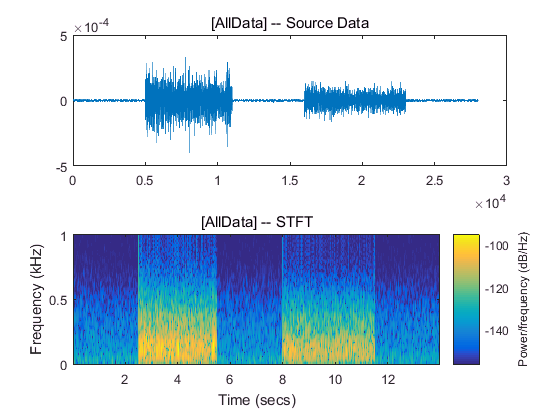

figure;
subplot(2,1,1)
plot(sEMG.AllData); % source data visualization
title('[AllData] -- Source Data');

subplot(2,1,2)
section = 60;
overlap = 20;
cyclical_f = 200;
spectrogram(sEMG.AllData, section, overlap, cyclical_f, Fs, 'yaxis')
title('[AllData] -- STFT');

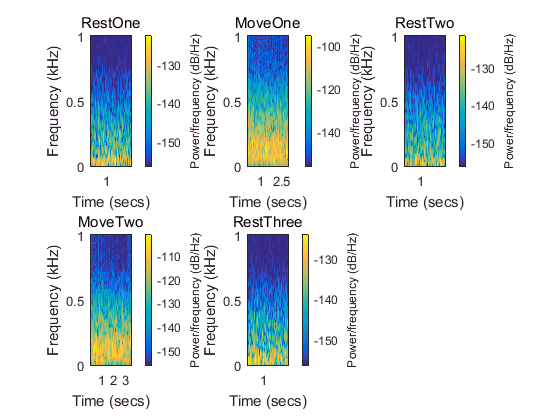

figure;
for p = 1:5
    subplot(2,3,p)
    spectrogram(sEMG.CellData{p}, section, overlap, cyclical_f, Fs, 'yaxis');
    title(sEMG.StringTitle{p});
end

**Conclusion:**

    It seem to be well-distributed horizontally.

    There is no much frequency fluctation  in short time period - on more than 5 seconds. 

**Preview **on combination of 3 **[Rest]** parts**. **

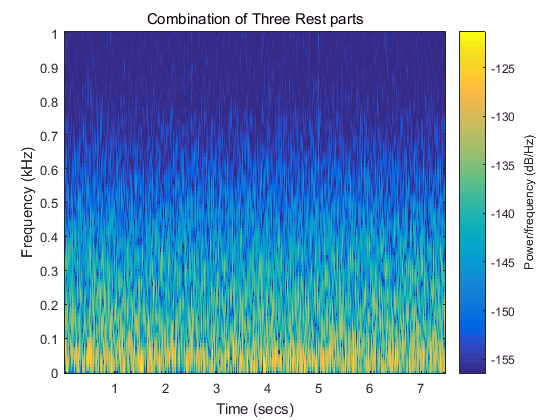

    figure;
    spectrogram([sEMG.RestOne; sEMG.RestTwo; sEMG.RestThree], section, overlap, cyclical_f, Fs, 'yaxis')
    title('Combination of Three Rest parts')

    **Conclusion:**

    Within time length of 7.5s, there is no oblivious difference for **Frequency **that depends on time. 

    **Advanced Idea:**

    1. Frequency variation calculated by STFT would be a chronic index for **model online updating** or **estimation of fatigue**. 

** 4.2 WT - Wavelet Transformation**

**    CWT - **Continious Wavelet Transformation

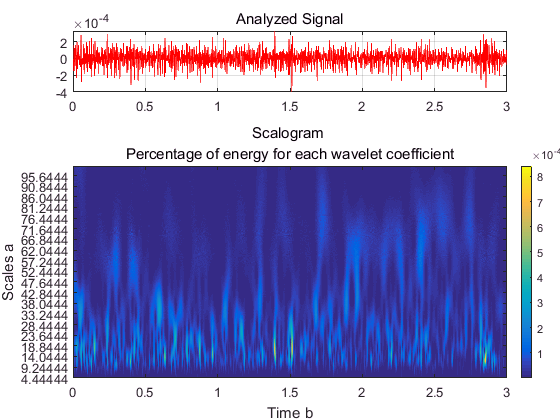

Fs = 2000;
x = [sEMG.RestOne; ...
     sEMG.RestTwo; ...
     sEMG.RestThree]; %nx1
x = [sEMG.MoveOne];
% x = sEMG.AllData;
fc = centfrq('cmor1-1'); % central frequency for specified wave-name
freqrange = [20 450]; % interesting frequency range
scalerange = fc./(freqrange*(1/Fs));
t = linspace(0,size(x,1)/Fs,size(x,1)); %(x1, x2, n), generate n points between [x1 x2]
scales = scalerange(end):0.2:scalerange(1);
Coeffs = cwt(x, scales, 'cmor1-1');
SCImg = wscalogram('image', Coeffs, ...
                   'scales', scales, ...
                   'ydata', x, ...
                   'xdata', t);
grid on;

**Inverse CWT and Signal Reconstruction **based on Fourier Transformation

% freqrange [1 2]
indices = find(scales>=1/freqrange(2) & scales<=1/freqrange(1));